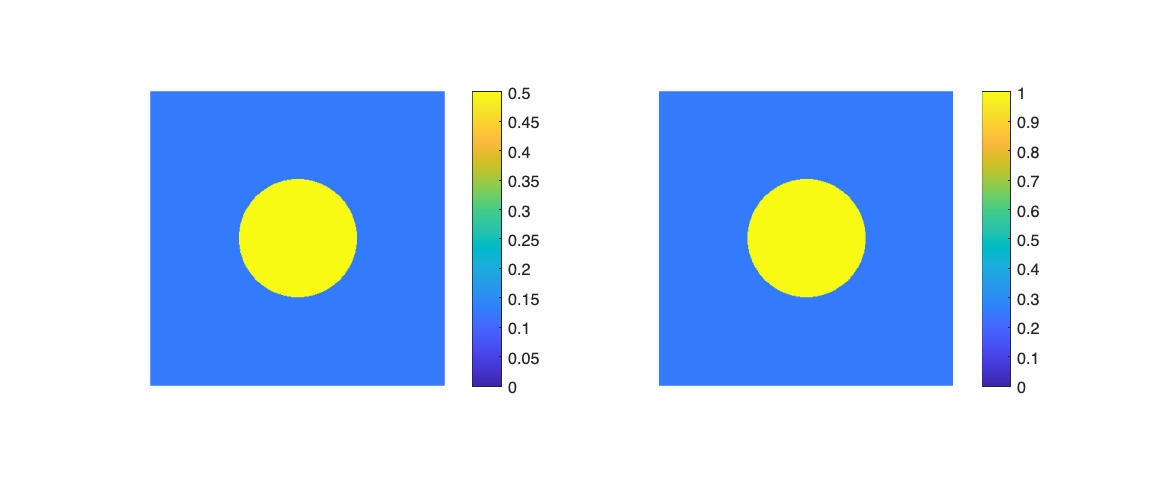

for i = 0:10:12940
    fname = "data-" + i + ".h5";
    dat = h5read(fname, '/Solution');
    
    subplot(1, 2, 1);
    h = pcolor(squeeze(dat(:,:,1))');
    set(h, LineStyle='none');
    axis equal; axis tight; axis off; clim([0,0.5]);
    colorbar;

    subplot(1, 2, 2);
    h = pcolor(squeeze(dat(:,:,4))');
    set(h, LineStyle='none');
    axis equal; axis tight; axis off; clim([0,1]);
    colorbar;

    set(gcf, Position=[0, 0, 1400, 600]);
    saveas(gcf, "plot-" + i + ".png", 'png');
end